clear; clc;
syms x [1 4] 'real';
syms u 'real';
m1 = 5;  % (kg) Cart mass
m2 = 1;  % (kg) pole mass
l = 2;   % (m) pendulum (pole) length

## Linearization

[A, B] = cartpole_dynamics2(x, m1, m2, l);
A = jacobian(A, x);

fixed_point = [0, 0, 0, 0];
A = subs(A, x, fixed_point);
A = eval(A);
eig(A)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 2.4261i
   0.0000 - 2.4261i


B = subs(B, x, fixed_point);
B = eval(B)

B =          0
         0
    0.2000
   -0.1000


## Control Setup

controllability = det(ctrb(A,B))

controllability = -0.0096

Q = [10 0 0 0;
    0 10 0 0;
    0 0 1 0;
    0 0 0 1];
R = 0.01;

Kr = lqr(A,B,Q,R);
eig(A-B*Kr)

ans =   -1.9106 + 1.6165i
  -1.9106 - 1.6165i
  -0.5145 + 2.1652i
  -0.5145 - 2.1652i


## Estimation Setup

C = [1 0 0 0];
D = [0 0 0 0];
observability = det(obsv(A, C))

observability = -3.8494

Vd = eye(4);  % disturbance covariance
Vn = 1;       % noise covariance
Kf = (lqr(A',C',Vd,Vn))';
eig(A-Kf*C)

ans =   -0.1620 + 2.4418i
  -0.1620 - 2.4418i
  -0.8906 + 0.4929i
  -0.8906 - 0.4929i


## Simulate System

Baug = [B eye(4) 0*B];
Daug = [D 0 1];

sysOriginal = ss(A,Baug,C,Daug);
sysTruth = ss(A,Baug,eye(4),zeros(4,size(Baug,2)));  
sysKF = ss(A-Kf*C,[B Kf],eye(4),0*[B Kf]);  % Kalman filter

dt = .01;
t = 0:dt:50;

uDIST = sqrt(Vd)*randn(4,size(t,2)); % random disturbance
uNOISE = sqrt(Vn)*randn(size(t));    % random noise
u = 0*t;
u(1/dt) = 20/dt;    % positive impulse
u(15/dt) = -20/dt;  % negative impulse

uAUG = [u; uDIST; uNOISE];  % input w/ disturbance and noise

[y,t] = lsim(sysOriginal,uAUG,t);         % noisy measurement
[xtrue,t] = lsim(sysTruth,uAUG,t); % true state
[xhat,t] = lsim(sysKF,[u; y'],t);  % state estimate

## Plot results

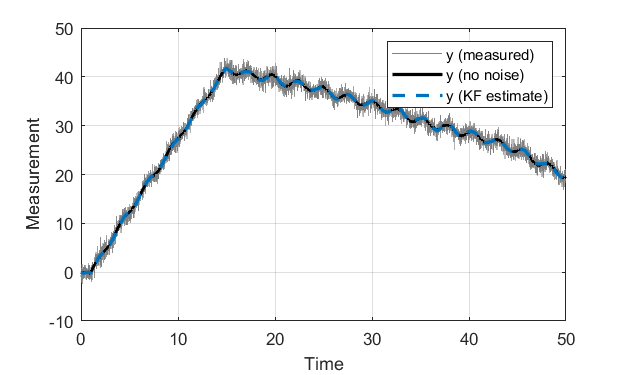

CC = [0    0.4470    0.7410
    0.8500    0.3250    0.0980
    0.9290    0.6940    0.1250
    0.4940    0.1840    0.5560
    0.4660    0.6740    0.1880
    0.3010    0.7450    0.9330
    0.6350    0.0780    0.1840];

figure
plot(t,y,'Color',[.5 .5 .5])
hold on
plot(t,xtrue(:,1),'Color',[0 0 0],'LineWidth',2)
plot(t,xhat(:,1),'--','Color',CC(1,:),'LineWidth',2)
set(gcf,'Position',[100 100 500 300])
xlabel('Time')
ylabel('Measurement')
l1 = legend('y (measured)','y (no noise)','y (KF estimate)');
set(l1,'Location','NorthEast')
grid on

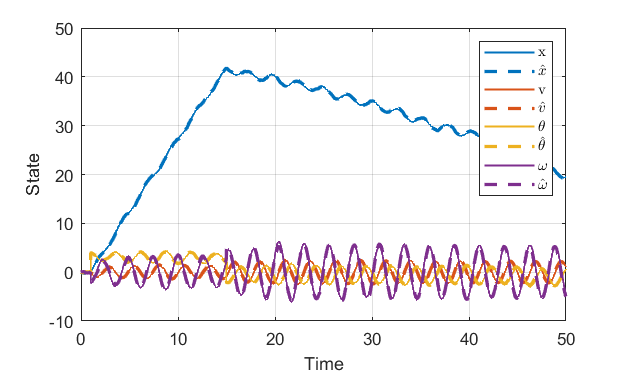

set(gcf,'PaperPositionMode','auto')
figure
for k=1:4
plot(t,xtrue(:,k),'-','LineWidth',1.2,'Color',CC(k,:));
hold on
plot(t,xhat(:,k),'--','LineWidth',2,'Color',CC(k,:))
end
set(gcf,'Position',[100 100 500 300])
xlabel('Time')
ylabel('State')
% l1 = legend('x','v','$\theta$','$\omega$','$\hat{x}$','$\hat{v}$','$\hat{\theta}$','$\hat{\omega}$');
l1 = legend('x','$\hat{x}$','v','$\hat{v}$','$\theta$','$\hat{\theta}$','$\omega$','$\hat{\omega}$');

set(l1,'Location','NorthEast','interpreter','latex')
grid on

set(gcf,'PaperPositionMode','auto')